# PhysioNet Challenge 2016: Classify normal and abnormal heart sounds

This script demonstrates the complete workflow for developing an embedded machine learning application,including acquiring the data, extracting features, exploring various algorithms, tuning to get a model with good performance, and  deploying the model in a prototype application. Specifically, we develop a classifier of heart sounds into 'Normal' and 'Abnormal', which could be used in the medical practice to monitor patients who are at increased risk of dangerous heart conditions, and remove the need to have a skilled clincian present. 

THIS SCRIPT IS INTENDED TO BE STEPPED THROUGH SECTION BY SECTION, because of the interactive Signal Analyzer and Classification Learner apps that it calls. If you try to run the complete script, errors are likely to occur.

The figure below shows the high-level architecture and a screenshot from the prototype.

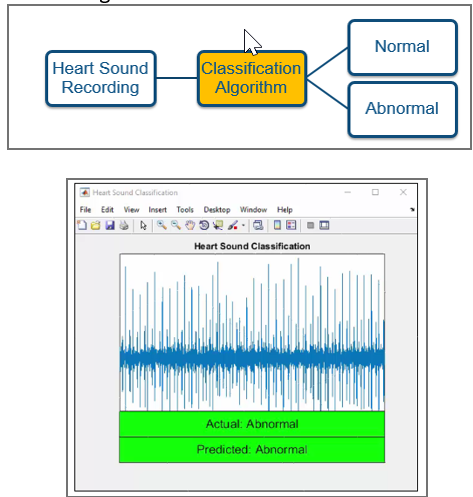

For this application, we use the dataset provided by the [PhysioNet challenge of 2016](https://physionet.org/challenge/), consisting of over 3000 recordings of normal and abnormal hearts. These recordings were obtained at four different locations - aortic, pulmonic, trcuspid and mitral areas - using phonocardiograms.

To get us started, we need to obtain the data. If you are running this for the first time, this step will download data from PhysioNet's website. This step will be skipped if the "Data" directory is present. Or if you don't intend to actually run feature extraction or train the models (both of which can take several minutes to execute), you don't have to worry about actually getting the training and validation dataset. Instead, just extract the demonstration zipfile (that's included) and you can simply load the precomputed features from the .mat file, and then train models in the Classification Learner App.

***Note***: This may take a while depending on your internet speed.

getTrainingData = 1;   % option to skip downloading training data (may take long time, 185 MB)
if ~exist('training.zip') && getTrainingData%#ok 
    % fetch training data from physionet site. 
    % NOTE: unless you plan to execute the feature extraction, don't worry if there is an error here,
    %       we only need access to the training set to run the feature extraction 
    try
        training_url = 'http://www.physionet.org/physiobank/database/challenge/2016/training.zip';
        websave('training.zip', training_url);
    catch
        warning("Failed to access heart sound training data on physionet.org - check your internet connection or whether path %s needs updating",training_url)
    end
    
    unzip('training.zip', 'Data\')
end

if ~exist('validation.zip')%#ok 
   % you need the validation data only for running the prototype app
   try
       validation_url = 'http://www.physionet.org/physiobank/database/challenge/2016/validation.zip';
       websave('validation.zip', validation_url);
   catch
       warning("Failed to access heart sound validation data on physionet.org - check whether path %s needs updating", validation_url)
   end
end
unzip('validation.zip','Data');


% make sure we have copies of the two example files in the main directory
if exist('Data\validation')%#ok
    copyfile 'Data\validation\a0001.wav';
    copyfile 'Data\validation\a0011.wav';
end

Add current folder and subfolders to search path, so the script can find the recordings in subdirectories of "Data", and various MATLAB functions in "HelperFunctions".

addpath(genpath(pwd));
addpath('HelperFunctions/');

The remainder of this demo is structured according to the four phases of the typical machine learning workflow:

- Access and Explore Data

- Preproess Data

- Develop Predictive Models

- Integrate Models with Systems

The figure below shows which additional MATLAB toolboxes we will leverage in the various phases of the workflow.

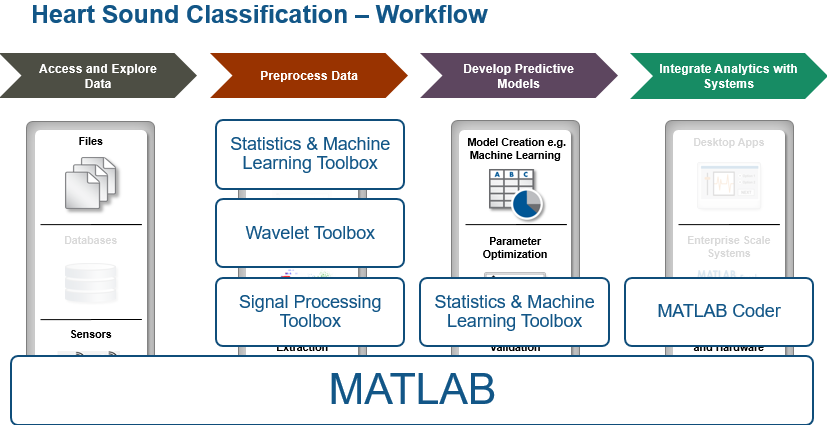

## 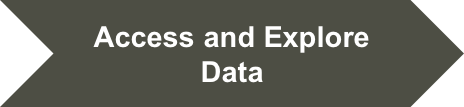

## What does an abnormal heart sound like?

Let's begin by forming an impression what these heart signals sound like. MATLAB provides functions to play back audio. For this exercise, we copied samples of normal and abnormal heart recordings from the dataset into the main directory.

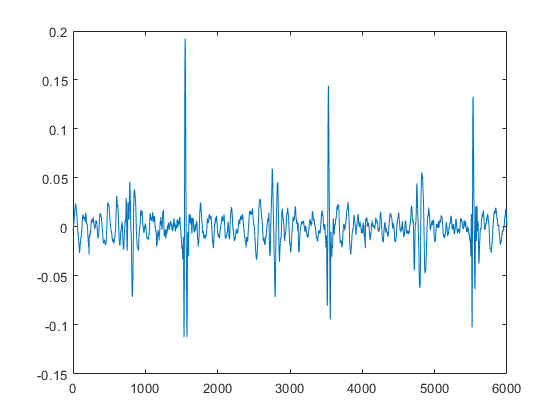

[PCG_abnormal, fs] = audioread('a0001.wav');
p_abnormal = audioplayer(PCG_abnormal, fs);
play(p_abnormal, [1 (get(p_abnormal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(PCG_abnormal(1:fs*3))

## What does a normal heart sound like?

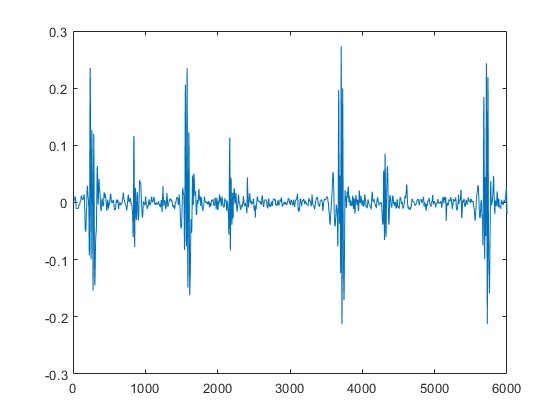

[PCG_normal, fs] = audioread('a0011.wav');
p_normal = audioplayer(PCG_normal, fs);
play(p_normal, [1 (get(p_normal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(PCG_normal(1:fs*3))

## 

## What do the signals look like in the frequency domain?

To explore what we might use to distinguish these signals with a classifier, let's look at their frequency content. To this end, you can use MATLAB's [Signal Analyzer](https://www.mathworks.com/help/signal/ug/getting-started-with-signal-analyzer-app.html) app to inspect and compare the power spectrum of the two signals.

signalAnalyzer(PCG_abnormal, PCG_normal)

Once the app has loaded, display the signals in two separate panels (use the Grid button on the left upper corner), and then generate the Spectrum underneath the waveform (by clicking the corresponding button). The abnormal sound will show a clear spike near 0.2 radians, whereas the normal sound has more frequency content right near the y-axis.

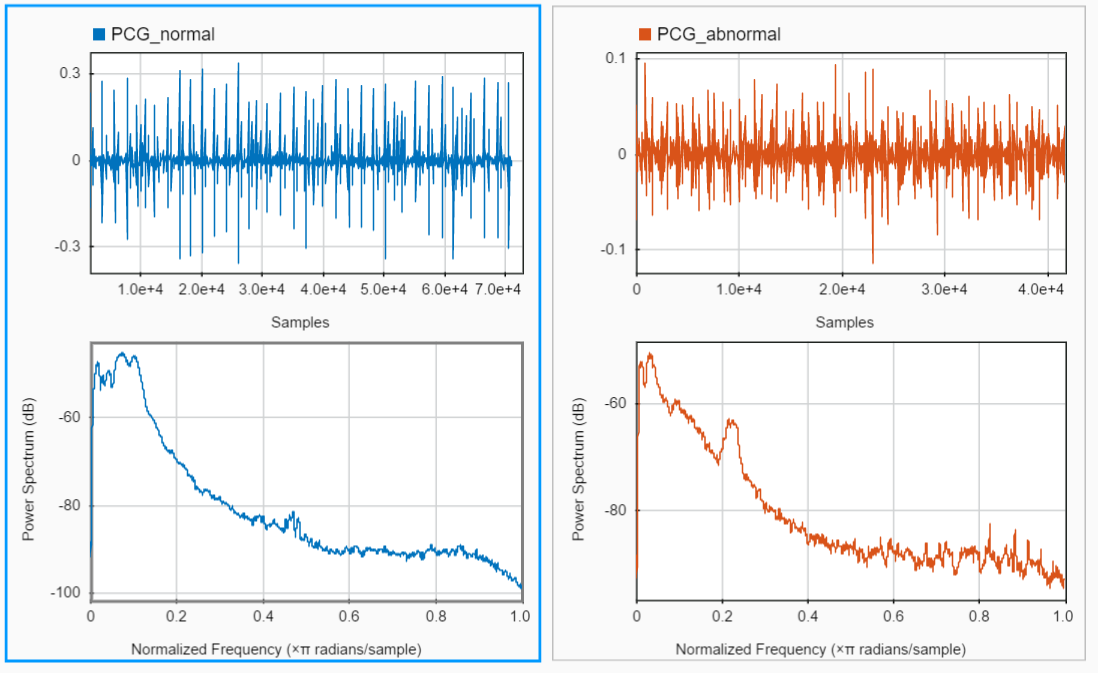

## 

## Prepare to read the data into memory

To load the recordings into memory, MATLAB's [fileDatastore](https://www.mathworks.com/help/matlab/ref/filedatastore.html) provides a convenient way to handle a large number of data files spread across multiple folders. The read function provides flexibility to access a wide variety of different file formats, and with MATLAB's base read functions typically little customization is needed. 

training_fds = fileDatastore(fullfile(pwd, 'Data', 'training'), 'ReadFcn', @importAudioFile, 'FileExtensions', '.wav', 'IncludeSubfolders', 1);

Error using fileDatastore (line 105)
Cannot find files or folders matching: 'C:\Users\jwhung\Dropbox\2018\MATLAB\matlab resources\HeartSoundClassificationNew\Data\training'.

## 

## Create a table with filenames and labels

"Labels" (or also "ground truth") represent the true category of each sample in a dataset and are critical to be able to apply  "supervised" machine learning to this classification task. The dataset we are using here provides the labels in a separate REFERENCE file in each subfolder of the training and validation data, along with the corresponding audio files (recordings). So in this section we read these REFERENCE.csv files and build a table with filename and corresponding label. This step is only needed if you want to run feature extraction in the next step.

data_dir = fullfile(pwd, 'Data', 'training');
folder_list = dir([data_dir filesep 'training*']);

reference_table = table();

for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = Normal, -1 = Abnormal
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

## 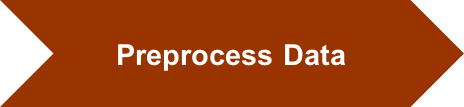

## Extract features from raw heart sound signals

Next we need to extract features from the raw recordings. We use statistical and signal processing functions available in MATLAB to process and extract features from the raw heart sound signal. The following section extracts 27 features for each recording, and splits each recording into windows consisting of 5 seconds of heart sound.

The preprocessing of all 3000+ recordings may take a while, even though the code below leverages the Parallel Computing toolbox to execute on multiple cores (provided your machine is multicore). To avoid waiting, by default the code will simply load the extracted features from the FeatureTable that we included with the demo.

if ~exist('FeatureTable.mat')%#ok 
    % Window length for feature extraction in seconds
    win_len = 5;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
    n_parts = numpartitions(training_fds, gcp);
    
    % Distribute computation across available processors by using parfor
    parfor ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        
        % Extract features for the sub datastore
        feature_table = [feature_table; extractFeatures(subds, win_len, win_overlap, reference_table)];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');
else % simply load the precomputed features
    load('FeatureTable.mat');
end

% Take a look at the feature table
disp(feature_table(1:5,:))

## 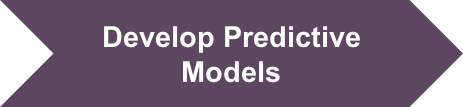

## Train, compare and select classifier 

Having an initial set of features, we can proceed to the next phase of the machine learning workflow, the training of various predictive models. You can use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to interactively train, compare and select classifiers.

classificationLearner

Select the "feature_table" variable from the workspace as your data, and either hold out 30% as model "validation" data, or (to preserve more data for training) choose cross validation. 

Then train a bunch of different classifiers, including linear regression, SVM, and decision trees. Note which ones deliver higher accuracy on the held out validation data. Also explore the confusion matrices and conceptualize what misclassifying a normal versus an abnormal sound means in practice.

A fairly high number of abnormal sounds are misclassified as normal, which is very undesirable in medical practice because it means failing to diagnose someone who might have a serious heart condition. To improve model performance, the following sections will apply additional optimization steps.

## 

## Split data into training and testing sets. 

These optimization steps need to be performed programmatically. Therefore, we first need to split the data like we did within the Classification Learner app, and to match our work in the app, holding out 30% of the (training) data for testing. Use [cvpartition](https://www.mathworks.com/help/stats/cvpartition.html) to split data into training and testing sets. Use [grpstats](https://www.mathworks.com/help/stats/grpstats.html) to tally number of observations for each class.

rng(1)
% Use 30% of data for training and remaining for testing
split_training_testing = cvpartition(feature_table.class, 'Holdout', 0.3       );

% Create a training set
training_set = feature_table(split_training_testing.training, :);

% Create a test set (won't be used until much later)
testing_set = feature_table(split_training_testing.test, :);

grpstats_training = grpstats(training_set, 'class', 'mean');
disp(grpstats_training(:,'GroupCount'))


## 

## Train the classifier with misclassification cost

To compensate for fewer 'Abnormal' observations in the data, and to bias the classifier towards fewer misclassifications of abnormal sounds, we use a cost function that assigns higher misclassification cost to the 'Abnormal' class. At the same time, we perform hyperparameter tuning by using [Bayesian Optimization](https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html) to find optimal values for model parameters. 

Since the ensemble of trees outperformed the SVM classifier in the Classification Learner, we continue with the ensemble. 

% Assign higher cost for misclassification of abnormal heart sounds
C = [0, 20; 1, 0];

% Create a random sub sample (to speed up training) from the training set
%subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
subsample = 1:height(training_set);

rng(1);

% Create a 5-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',5);

if ~exist('TrainedEnsembleModel.mat')%#ok
    % perform training only if we don't find a saved model

    % train ensemble of decision trees (random forest)
    disp("Training Ensemble classifier...")
    
    % bayesian optimization parameters (stop after 15 iterations)
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',15);    
    trained_model = fitcensemble(training_set(subsample,:),'class','Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'},...
        'HyperparameterOptimizationOptions',opts)

    save('TrainedEnsembleModel', 'trained_model');
else
    % load previously saved model
    load('TrainedEnsembleModel.mat')
end

% Predict class labels for the validation set using trained model
% NOTE: if training ensemble without optimization, need to use trained_model.Trained{idx} to predict
predicted_class = predict(trained_model, testing_set);

conf_mat = confusionmat(testing_set.class, predicted_class);

conf_mat_per = conf_mat*100./sum(conf_mat, 2);

% Visualize model performance in heatmap
labels = {'Abnormal', 'Normal'};
heatmap(labels, labels, conf_mat_per, 'Colormap', winter, 'ColorbarVisible','off');

## 

## Perform feature selection using Neighborhood Component Analysis

The last model performs pretty well, but it is too large for deployment on a small embedded device. Therefore, in this section we explore training a more compact model that uses only a subset of the 26 features, namely the features that have the majority of the predictive power. [Neighborhood Component Analysis](https://www.mathworks.com/help/stats/neighborhood-component-analysis.html) (NCA) is an automated approach for  selecting a small subset of features that carry information most relevant to the classification task while minimizing redudancy among selected features. 

runNCA = 1;   % set this to 0 to skip

if ~runNCA && exist('SelectedFeatures.mat')%#ok
    % Load saved array of selected feature indexes
    load('SelectedFeatures.mat')
else % Perform feature selection with neighborhood component analysis
    rng(1)
    mdl = fscnca(table2array(training_set(:,1:27)), ...
        table2array(training_set(:,28)), 'Lambda', 0.005, 'Verbose', 0);
    
    % Select features with weight above 1
    selected_feature_indx = find(mdl.FeatureWeights > 0.1);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    
    save('SelectedFeatures.mat','selected_feature_indx');
end

% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))

## 

## Train model with selected features

To actually get a more compact model for deployment, we retrain the model using only selected features. Note how the file size decreased from 6G to 4G - maybe still not small enough, we could explore other models instead.

if ~exist('TrainedEnsembleModel_FeatSel.mat')%#ok
    rng(1)
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',15);    
    trained_model_featsel = fitcensemble(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'}, 'HyperparameterOptimizationOptions',opts)
    save('TrainedEnsembleModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedEnsembleModel_FeatSel.mat')
end

% Predict class labels for the validation set using trained model
predicted_class_featsel = predict(trained_model_featsel, testing_set(:,selected_feature_indx));

conf_mat_featsel = confusionmat(testing_set.class, predicted_class_featsel);

conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);

labels = {'Abnormal', 'Normal'};

% Visualize model performance
% probably custom AE version: heatmap(conf_mat_per_featsel, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);
heatmap(labels,labels,conf_mat_per_featsel, 'Colormap', winter, 'ColorbarVisible','off');

## 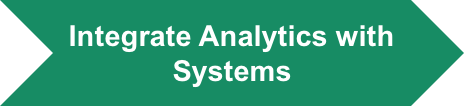

## Code Generation

Generate C code that takes recorded signal and sampling frequency as input and produces heart sound classification label as output. Be patient since this process can take several minutes!

% Save trained model as a compact model for code generation
saveCompactModel(trained_model_featsel,'HeartSoundClassificationModel');

% Alternatively, execute the following auto-generated MATLAB script to generate C code (and mex file, in current directory)
classifyHeartSounds_codegen_script

copyfile codegen\mex\classifyHeartSounds\classifyHeartSounds_mex.mexw64 HelperFunctions\

## Validate final model

Process a subset of audio files from the validation set (located in the 'demonstration' subfolder) by the sample app. The app calls the mex version of the function "classifyHeartSounds"

plotPredictions

*Copyright 2017 The MathWorks, Inc.*